## 利用MLE方法估计参数

观测数据为：

A = [1 0 1 1 0];  % 意大利
B = [1 1 0 0 0];  % 英格兰

代入$p_A=0.8412698 ,q_B=0.8554217$，得到该比分的概率为：

p_sym = simplify(ABAB_p(A,B))

$$p\_sym = -{\left(\Delta +\mathrm{pA}\right)}^{2}\,\left(\Delta +\mathrm{qB}\right)\,\left(\mathrm{al}-\mathrm{qB}\right)\,\left(\mathrm{qB}-1\right)\,\left(\Delta +\mathrm{pA}-1\right)\,\left(\mathrm{al}-\mathrm{qB}+1\right)\,\left(\Delta -\mathrm{al}+\mathrm{pA}\right)\,\left(\Delta +\mathrm{al}+\mathrm{pA}-1\right)\,\left(\Delta -\mathrm{al}+\mathrm{qB}-1\right)$$

syms pA qB al Delta
p_sym = subs(p_sym,{pA,qB},{0.8412698,0.8554217})

$$p\_sym = -\frac{162780694501465\,\left(\mathrm{al}+\frac{162780694501465}{1125899906842624}\right)\,{\left(\Delta +\frac{7577484715596103}{9007199254740992}\right)}^{2}\,\left(\Delta +\frac{963119212341159}{1125899906842624}\right)\,\left(\mathrm{al}-\frac{963119212341159}{1125899906842624}\right)\,\left(\Delta -\frac{1429714539144889}{9007199254740992}\right)\,\left(\Delta -\mathrm{al}+\frac{7577484715596103}{9007199254740992}\right)\,\left(\Delta +\mathrm{al}-\frac{1429714539144889}{9007199254740992}\right)\,\left(\mathrm{al}-\Delta +\frac{162780694501465}{1125899906842624}\right)}{1125899906842624}$$

## 似然函数等高线图

得到数据：

% 各轮两队概率
p_fac = [pA+Delta,qB-al,1-pA-Delta,qB+Delta,pA+Delta-al,1-qB,pA+Delta,1-qB+al,1-pA-Delta-al,1-qB-Delta+al];  
p_fac = subs(p_fac,{pA,qB},{0.8412698,0.8554217});
[X,Y] = meshgrid(0:0.01:0.15,0:0.01:0.15);
Z = X;
for i = 1:length(X)
    for j = 1:length(X)
        Z(i,j) = subs(p_sym,{al,Delta},{X(i,j),Y(i,j)});
        a = double(subs(p_fac,{al,Delta},{X(i,j),Y(i,j)}));
        if any(a<0 | a>1)
            Z(i,j) = 0;
        end
    end
end

绘图等高线图：

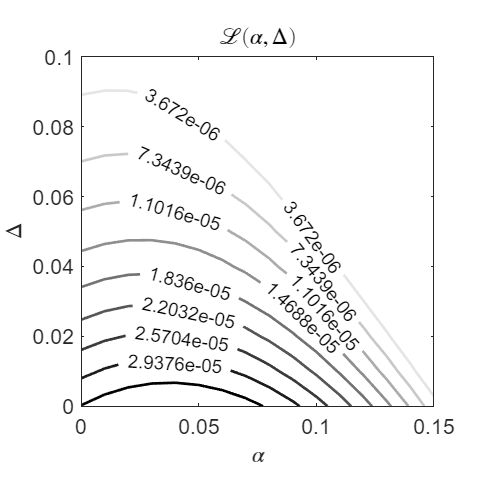

% 绘图
close all
f = figure('Units','inches','Position',[0 0 5 5]);
[M,c] = contour(X,Y,Z,9);
ylim([0,0.1]);
c.LineWidth = 2;
c.ShowText = 'on';
clabel(M,c,'FontSize',14) 
xlabel('$\alpha$','Interpreter','latex','FontSize',16);
ylabel('$\Delta$','Interpreter','latex','FontSize',16);
str = "$\mathcal{L}(\alpha,\,\Delta)$";
title(str,'Interpreter','latex','FontSize',16);
set(gca,'fontsize',16);
cl = gray;
cl = flipud(cl(1:230,:));
colormap(cl);
pbaspect([1 0.99 1])


% exportgraphics(gcf,'pic/Delta_alpha_est.pdf','ContentType','vector','Resolution',300);

## MAP的等高线图

先验分布：

syms m1 s1 x
PP = 1/(s1*sqrt(2*pi))*exp(-(x-m1)^2/(2*s1^2))

$$PP = \frac{2251799813685248\,{\mathrm{e}}^{-\frac{{\left(m_{1}-x\right)}^{2}}{2\,{s_{1}}^{2}}}}{5644425081792261\,s_{1}}$$

PP_al = subs(PP, {m1, s1}, {0, 0.5})

$$PP\_al = \frac{4503599627370496\,{\mathrm{e}}^{-2\,x^{2}}}{5644425081792261}$$

PP_Delta = subs(PP, {m1, s1}, {0, 0.5})

$$PP\_Delta = \frac{4503599627370496\,{\mathrm{e}}^{-2\,x^{2}}}{5644425081792261}$$

Z1 = X;
for i = 1:length(X)
    for j = 1:length(X)
        Z1(i,j) = subs(PP_al,{x},{X(i,j)}) * subs(PP_Delta,{x},{Y(i,j)});
    end
end

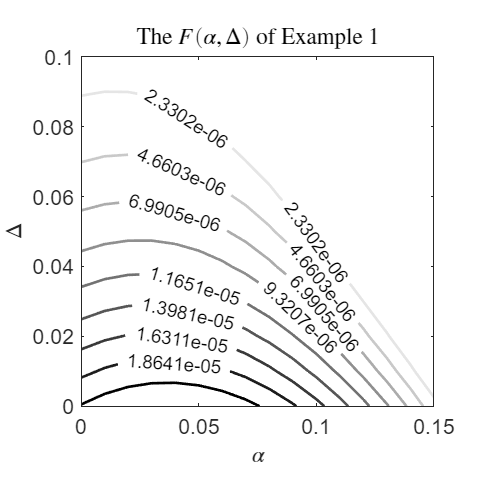

% 绘图
Z0  = Z .* Z1;
close all
f = figure('Units','inches','Position',[0 0 5 5]);
[M,c] = contour(X,Y,Z0,9);
ylim([0,0.1]);
c.LineWidth = 2;
c.ShowText = 'on';
clabel(M,c,'FontSize',14) 
xlabel('$\alpha$','Interpreter','latex','FontSize',16);
ylabel('$\Delta$','Interpreter','latex','FontSize',16);
str = "The $F(\alpha,\,\Delta)$ of Example 1";
title(str,'Interpreter','latex','FontSize',16);
set(gca,'fontsize',16);
cl = gray;
cl = flipud(cl(1:230,:));
colormap(cl);
pbaspect([1 0.99 1])

%exportgraphics(gcf,'pic/MAP.pdf','ContentType','vector','Resolution',300);